clearvars
close all

trans = [0.95,0.05;
      0.10,0.90];
emis = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;
   1/10, 1/10, 1/10, 1/10, 1/10, 1/2];

seq1 = hmmgenerate(100,trans,emis);

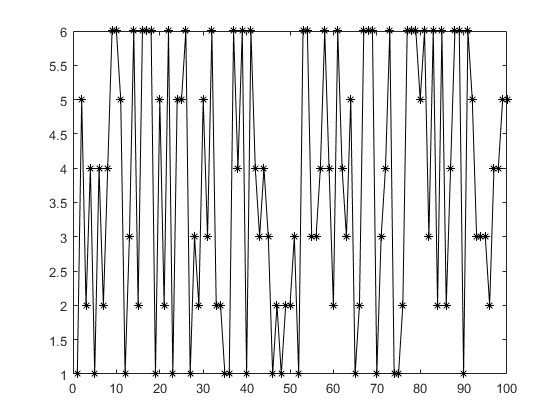

plot(seq1,'-*k');

seq1

seq1 =      1     5     2     4     1     4     2     4     6     6     5     1     3     6     2     6     6     6     1     5     2     6     1     5     5     6     1     3     2     5     3     6     2     2     1     1     6     4     6     1     6     4     3     4     3     1     2     1     2     2


trans = [0.85,0.15;
      0.50,0.50];
emis = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;
   1/6, 1/6, 1/6, 1/6, 1/6, 1/6];


[estTR,estE] = hmmtrain(seq1,trans,emis,"Verbose",true,"Maxiterations",1000)

Relative Changes in Log Likelihood, Transition Matrix and Emission Matrix
   Iteration       Log Lik    Transition     Emmission
       2         0.0305609    9.0338e-05    0.00107186
       3       9.66147e-06   0.000174395    0.00106006
       4       9.51784e-06   0.000255362    0.00105926
       5        9.7336e-06   0.000335923    0.00106849
       6       1.02825e-05   0.000418454    0.00110066
       7         1.116e-05   0.000505191    0.00114405
       8       1.23808e-05   0.000598363    0.00119247
       9       1.39777e-05   0.000700307    0.00124622
      10       1.60023e-05    0.00081358    0.00130562
      11       1.85263e-05   0.000941064    0.00137108
      12       2.16449e-05    0.00108607    0.00144297
      13       2.54811e-05    0.00125245    0.00157745
      14       3.01923e-05     0.0014447    0.00174758
      15       3.59784e-05    0.00166806    0.00193665
      16       4.30922e-05    0.00192863    0.00214667
      17       5.18531e-05    0.00223336    0.

estTR =     0.7624    0.2376
    0.2830    0.7170


estE =     0.2357    0.1508    0.0707    0.0000    0.2024    0.3405
    0.0918    0.1710    0.2225    0.2848    0.0000    0.2299


tm = full(sparse(seq1(1:end-1),seq1(2:end),1)) % the transition matrix.

tm =      2     4     3     1     3     4
     2     2     1     4     1     6
     2     2     3     3     1     3
     1     2     3     1     1     5
     2     2     2     0     2     2
     7     4     2     4     3     9
